%Cargamos los parametros de la camara despues de obtenerlos de la sesion de
%calibracion
ld = load("cameraParams.mat"); %Cargamos los parametros de la camara 
intrinsics = ld.cameraParams.Intrinsics; %Cargamos unicamente los parametros intrinsecos de la camara

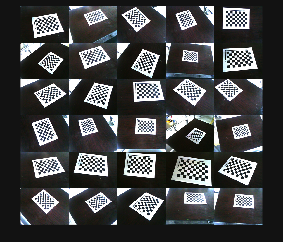

%Cargamos las imagenes que tenemos en la carpeta de de donde estan las fotos con 
% sus respectivas poses y decimos cuantas poses fueron en total 
%(esta es igual al numero de fotos)
numPoses = 30; %Colocamos el numero de fotos que tomamos 
imds = imageDatastore("COBOTPOSES"); %Cargamos todas las fotos tomadas en orden 
montage(imds) %Realiazmos el montaje de las fotos en orden por nombre

squareSize = 0.022; %Colocamos la medidas de los cubos en metros
camExtrinsics(numPoses,1) = rigidtform3d; %Creamos matrices de identidad de 4x4 (con 1 en diagonal)

%Estimamos la transoformada del tablero hacia la camara para cada pose
for i = 1:numPoses
    %Leemos cada imagen y utilizamos los parametros intrinsecos para quitar
    %la distorcion de cada imagen y la guardamos
    calibrationImage = readimage(imds,i);
    undistortedImage = undistortImage(calibrationImage,intrinsics);
    % Estimamos los valores extrinsecos mientras no se lee el tablero de
    % ajedrez, para poder detectar bien el origen del tablero en cada
    % imagen
    [imagePoints, boardSize] = detectCheckerboardPoints(undistortedImage,PartialDetections=false);
    worldPoints = patternWorldPoints("checkerboard",boardSize,squareSize);
    camExtrinsics(i) = estimateExtrinsics(imagePoints,worldPoints,intrinsics);
end

%Cargamos los datos y tabla que contiene las configuraciones de las juntas
%para cada foto
jointConfiguration = load("jntconfig.mat");
jointPositionsDeg = jointConfiguration.TablaDatos;
jointPositionsDeg = table2array(jointPositionsDeg); %La volvemos un arreglo

%Cargamos el modelo del robot al que queremos aplicar la configuracion
robotModel = loadrobot("universalUR5e");
robotModel.DataFormat = "column";
        % Creamos el nuevo cuerpo del gripper
        gripper = rigidBody("robotiq_gripper");
        % Creamos una junta fija para conectar el gripper al cuerpo anterior
        jnt = rigidBodyJoint("gripper_fixed", "fixed");
        % Ajustamos aquí la posición real del gripper respecto al último eslabón
        setFixedTransform(jnt, trvec2tform([0, 0, 0.16])); % Ajustamos el vector si es necesario
        gripper.Joint = jnt;
        % Agregamos el gripper como hijo del último cuerpo (por ejemplo "tool0")
        addBody(robotModel, gripper, "tool0");
%Creamos un espacio de matrices del EFECTOR FINAL a la BASE (Matrices de
%identidad)
endEffectorToBaseTform(numPoses,1) = rigidtform3d;
for i = 1:numPoses
    jointPositionsRad = deg2rad(jointPositionsDeg(i,:))'; %Convertimos de grados a radianes los angulos de las juntas
    endEffectorToBaseTform(i) = getTransform(robotModel,jointPositionsRad,"robotiq_gripper"); %Calculamos la transformada de cada pose
    %del efector final a la base del cobot
end

%Estima la transformada de la camara con respecto al efector final
config = "moving-camera";
cameraToEndEffectorTform = estimateCameraRobotTransform(camExtrinsics,endEffectorToBaseTform,config)

cameraToEndEffectorTform =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.0228 0.0432 -0.1409]
                 R: [3×3 double]

                 A: [-0.9981    0.0539   -0.0290    0.0228
                     -0.0612   -0.8658    0.4966    0.0432
                      0.0017    0.4974    0.8675   -0.1409
                           0         0         0    1.0000]


%Parámetros intrínsecos de una cámara: características internas del sistema óptico (distancia focal, centro óptico, distorsión del lente).
%Parámetros extrínsecos: describen la posición y orientación de la cámara en el espacio (respecto a un sistema de coordenadas del mundo).

% Suponiendo que ya tienes la transformada cameraToEndEffectorTform
% con una matriz de rotación 3x3 y una traslación 1x3
% Extraemos al matriz de rotación
R = cameraToEndEffectorTform.R;
% Extraemos el eje Z de la cámara expresado en el marco del efector
z_cam_in_eef = R(:,3);
% Definimos el eje Z del efector final (referencia)
z_eef = [0; 0; 1];
% Calculamos el ángulo entre ambos vectores
cos_theta = dot(z_cam_in_eef, z_eef) / (norm(z_cam_in_eef) * norm(z_eef));
angle_rad = acos(cos_theta);
% Convertimos a grados
angle_deg = rad2deg(angle_rad);
%El ángulo de inclinación del eje Z de la cámara respecto al eje Z del efector
fprintf('Inclinacion de la camara: %.4f grados\n', angle_deg);

Inclinacion de la camara: 29.8293 grados
